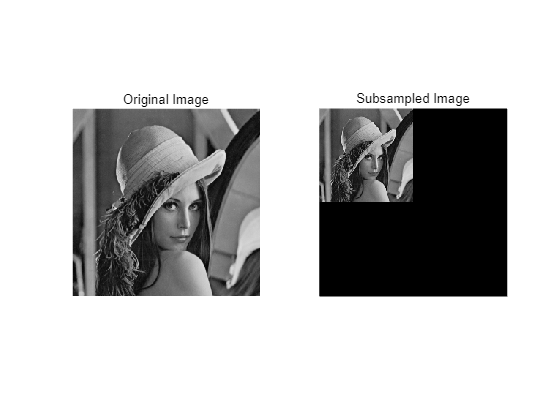

img = imread('C:\Users\HP\Desktop\上课\人工智能b\LabImages\Image\lena.bmp');

% Subsample the image
subsampled = subsample(img);
figure;
subplot(1,2,1); imshow(img); title('Original Image');
subplot(1,2,2); imshow(uint8(subsampled)); title('Subsampled Image');


%test walk
img_walk = imread('C:\Users\HP\Desktop\上课\人工智能b\LabImages\WalkSequence\Colour\walking_15.png');
img_walk = rgb2gray(img_walk)

img_walk = 240×320 uint8 矩阵
   159   159   158   159   153   127    96    93   103   107   112   117   117    98    68    55    41    27    25    28    35    43    50    56    65    70    65    49    47    43    30    30    31    32    34    34    34    32    32    34    44    65    82    85    72    45    29    42    64    91
   161   161   160   156   161   162   139   117   106    98    98   103   109   107   103   102    88    60    39    35    35    37    39    41    48    59    62    52    49    41    32    33    33    34    36    35    33    30    30    31    34    43    59    78    84    72    50    34    34    56
   152   152   160   160   163   164   154   146   141   127   115   115   112   109   108   102   108   116    91    53    39    38    36    35    36    38    43    51    56    47    37    35    33    34    37    36    46    54    37    27    34    33    30    34    49    60    65    84    97    83
   160   160   159   159   163   162   153   146   141   136   136   

% Subsample
subsampled01 = subsample(img_walk)

subsampled01 = 240×320 uint8 矩阵
   159   158   153    96   103   112   117    68    41    25    35    50    65    65    47    30    31    34    34    32    44    82    72    29    64   109    75   102    89    97    97    92    97   104   101   101   101    97   100   101   110   100   103    99    97    98    92    97    95    97
   152   160   163   154   141   115   112   108   108    91    39    36    36    43    56    37    33    37    46    37    34    30    49    65    97    42    42    96    94    89   101   102   107   100   105    96    92   100    97   104   104   103    99   100    94    85    93    89   101    93
   153   156   160   158   143   135   135   137   128    95    76    85    72    47    40    39    42    41    72    76    57    39    22    43   105    84    66    92    93    98    98   102    99   101    97    96    96   102   110   110   110   103    97    95    94    95    92   100   102    95
    86    74   111   147   151   144   139   136   139   137   13

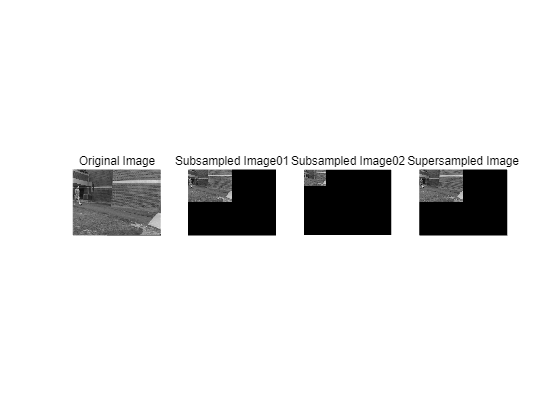

subsampled02 = subsample(subsampled01);

% Supersample
supersampled03 = supersample(subsampled02);%？为什么没有变化

figure;
subplot(1,4,1); imshow(img_walk); title('Original Image');
subplot(1,4,2); imshow(uint8(subsampled01)); title('Subsampled Image01');
subplot(1,4,3); imshow(uint8(subsampled02)); title('Subsampled Image02');
subplot(1,4,4); imshow(uint8(supersampled03)); title('Supersampled Image');

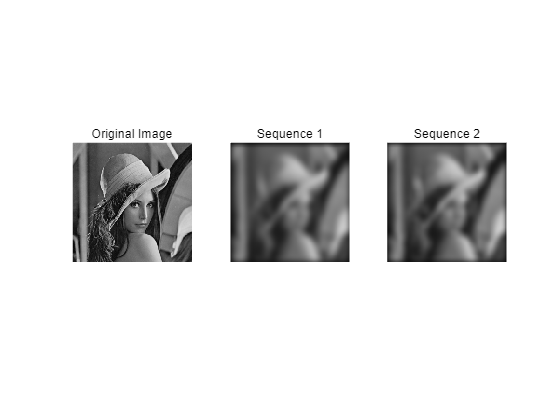



image = imread('C:\Users\HP\Desktop\上课\人工智能b\LabImages\Image\lena.bmp'); 


%last one
sequence1 = gaussSuperSample(gaussSuperSample(gaussianSubsample(gaussianSubsample(image))));
sequence2 = gaussSuperSample(gaussSuperSample(subsample(subsample(image))));
figure;
subplot(1, 3, 1);
imshow(image);
title('Original Image');
subplot(1, 3, 2);
imshow(sequence1);
title('Sequence 1');
subplot(1, 3, 3);
imshow(sequence2);
title('Sequence 2');

function smoothed = gaussianSmooth(image)
    gaussianFilter = fspecial('gaussian', [5 5], 2);
    smoothed = imfilter(image, gaussianFilter);
end

function subsampled = gaussianSubsample(image)
    smoothed = gaussianSmooth(image);
    subsampled = subsample(smoothed);
end

function supersampled = gaussSuperSample(image)
    smoothed = gaussianSmooth(image);
    supersampled = supersample(smoothed);
end


function supersampled_img = supersample(input_img)
    [rows, cols, channels] = size(input_img);
    supersampled_img = zeros(rows, cols, channels, class(input_img));
    
    for i = 1:rows/2
        for j = 1:cols/2
            supersampled_img(2*i-1, 2*j-1, :) = input_img(i, j, :);
            supersampled_img(2*i, 2*j-1, :) = input_img(i, j, :);
            supersampled_img(2*i-1, 2*j, :) = input_img(i, j, :);
            supersampled_img(2*i, 2*j, :) = input_img(i, j, :);
        end
    end
end




function subsampled_img = subsample(input_img)
    [rows, cols, channels] = size(input_img);
    subsampled_img = zeros(rows, cols, channels, class(input_img));
    for i= 1:rows/2
        for j = 1: cols/2
            subsampled_img(i,j, :) = input_img(2*i-1, 2*j-1, :);
        end
    end
end
